Fs = 8000;
F1 = 1000;
A1 = 0.9;
F2 = 1500;
A2 = 0.9;
L  = 100;

p1 = create_pole(A1,F1,Fs);
p2 = create_pole(A2,F2,Fs);

p = [p1 p2 conj(p1) conj(p2)];
[b, a] = zp2tf([],p,1);

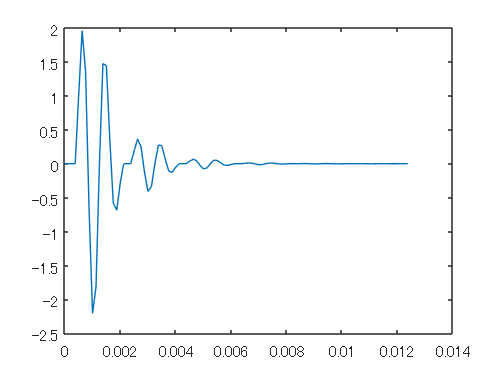

[h,t] = impz(b,a,L,fs);
plot(t,h)

fs = 8000;
TIME = 1;
t = 0:1/fs:TIME;
x = synthSaw(300,t,fs);
y = filter(b,a,x);
soundsc(y,fs)

function p = create_pole(A,F,Fs)
    theta = 2*pi*F/Fs;
    p = A*(cos(theta)+1j*sin(theta));
end